# Analisis de estabilidad

run parametros_y_especif.mlx
format short g

Rs = linspace(1.02,1.32,5);
len = length(Rs);

% Siendo las entradas
% Por el torque de carga
num_Tl = -1/r *[Lq*ones([len, 1])  Rs'];

% Entrada manipulada vqs
num_Vqs = [3/2 * Pp *lambda_m];

% Y el denominador comun


den = [(Jeq*Lq)*ones([len,1]) [(Lq*beq +Rs*Jeq)]' [(Rs*beq + 3/2*(Pp^2)*(lambda_m^2))]' zeros([len,1])];

## Polos del sistema

Los polos del sistema se obtienen de las raices del denominador, por ello se calculan directamente como

disp('Los polos del sistema seran');

Los polos del sistema seran


clf
for i=1:len
    txt = string(Rs(i));
    disp('Para Rs = '+ txt)
    polos = roots(den(i,:))
    plot(polos,'x',"DisplayName",txt,"MarkerSize",10,"LineWidth",2);
    hold on
end

Para Rs = 1.02


polos =             0 +          0i
      -89.258 +     301.57i
      -89.258 -     301.57i


Para Rs = 1.095


polos =             0 +          0i
      -95.724 +     299.64i
      -95.724 -     299.64i


Para Rs = 1.17


polos =             0 +          0i
      -102.19 +     297.56i
      -102.19 -     297.56i


Para Rs = 1.245


polos =             0 +          0i
      -108.65 +     295.31i
      -108.65 -     295.31i


Para Rs = 1.32


polos =             0 +          0i
      -115.12 +     292.91i
      -115.12 -     292.91i


lgd = legend

lgd =   Legend (1.02, 1.095, 1.17, 1.245, 1.32) with properties:

         String: {'1.02'  '1.095'  '1.17'  '1.245'  '1.32'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.74131 0.69556 0.14536 0.20476]
          Units: 'normalized'

  Show all properties


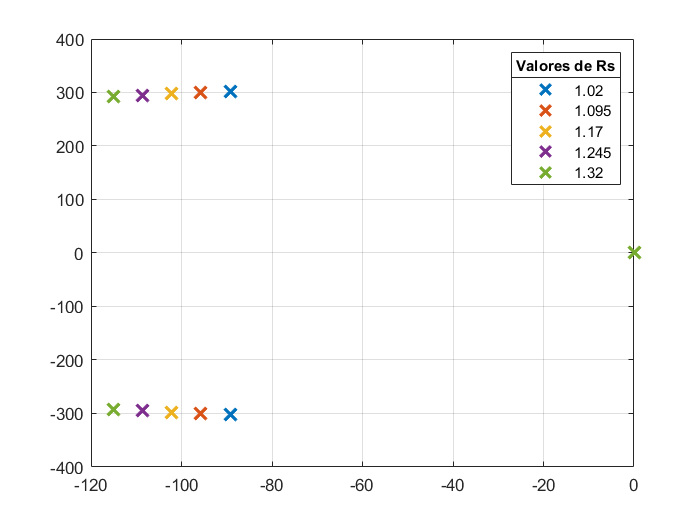

title(lgd,'Valores de Rs')
grid on

## Frecuencia y coef de amortiguamiento

Usando la funcion damp

for i=1:len
    txt = string(Rs(i));
    disp('Para Rs = '+ txt)
    [wn,z] = damp(tf(1,den(i,:)));
    disp('wn = ' + string(wn(end)));
    disp('zitta = ' + string(z(end)));
    disp(' ');
end

Para Rs = 1.02


wn = 314.5047


zitta = 0.28381


Para Rs = 1.095


wn = 314.5593


zitta = 0.30431


Para Rs = 1.17


wn = 314.6138


zitta = 0.32481


Para Rs = 1.245


wn = 314.6684


zitta = 0.3453


Para Rs = 1.32


wn = 314.7229


zitta = 0.36578


## Ceros del sistema

Solamente la entrada Tl proporciona ceros al sistema

disp('Los ceros del sistema con Tl seran');

Los ceros del sistema con Tl seran


ceros = []


ceros =

     []



clf
for i=1:len
    sys = tf(num_Tl(i,:),den(i,:));
    
    txt = string(Rs(i));
    disp('Para Rs = '+ txt)
    cero = zero(sys)
    
    polos = roots(den(i,:));
    polos(end+1) = cero;
    plot(polos(2:4),'o',"DisplayName",txt,"MarkerSize",10,"LineWidth",2);
    hold on
end

Para Rs = 1.02


cero =       -175.86


Para Rs = 1.095


cero =       -188.79


Para Rs = 1.17


cero =       -201.72


Para Rs = 1.245


cero =       -214.66


Para Rs = 1.32


cero =       -227.59


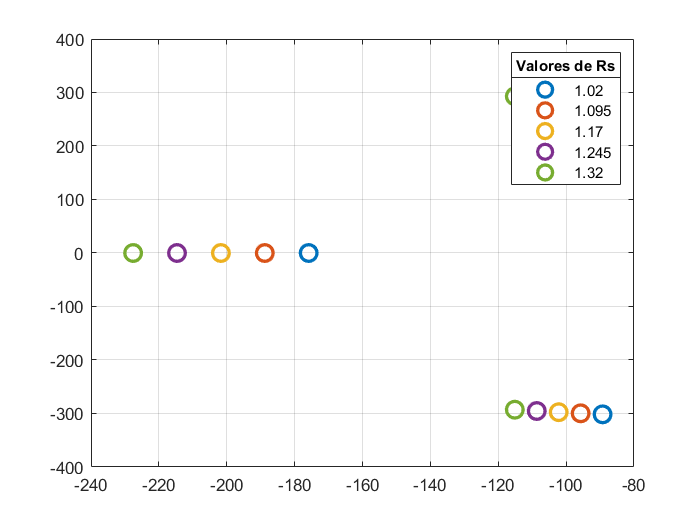

lgd = legend;
title(lgd,'Valores de Rs')
grid on